# Exploring grouped data with gramm

In this example file, we will go further in exploring gramm's capabilities for data where the independent variables are categorical / group data.

We will load a partial dataset from a human movement science experiment

load example_movement.mat
T

T = 3170×15 table
    subject    session    trial_index    reference_direction    hit    m_movement_duration    m_dist    m_reaction_time                 target_pos                  valid_perc    valid_perc_session                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

In this dataset, we have four different subjects (`subject`), each coming for two sessions (`session`) on consecutive days at the lab. During each of these sessions they learn to control the displacement of a cursor on a screen, and their task is to reach targets with the cursor. The targets are arranged at discrete angles (`reference direction`) in a circle around a starting point. The cursor is difficult to control, and as a marker for progress, we record whether they reach the target in time (`hit`), how long was their reaction time (`m_reaction_time`), their movement (`m_movement duration`), and what was the distance covered by the cursor (`m_dist`). Each line corresponds to a trial (`trial_index`), and we transformed the index in percentage of time elapsed within session (`valid_perc`) or across sessions (`valid_perc_session`)

## Using categorical data on the x axis

First let's examine the progress (using the reaction time `m_reaction_time`) between session for each subject. With gramm it's possible to use categorical data on the x axis and thus reproduce typical raw data plots or statistical data plots that would accompany analyses such as ANOVAs.

**To note:** To avoid points from both sessions to overlap, we use the `'dodge'` parameter in `geom_point()`. The numerical value indicates the spacing along the x axis used to avoid the overlap.

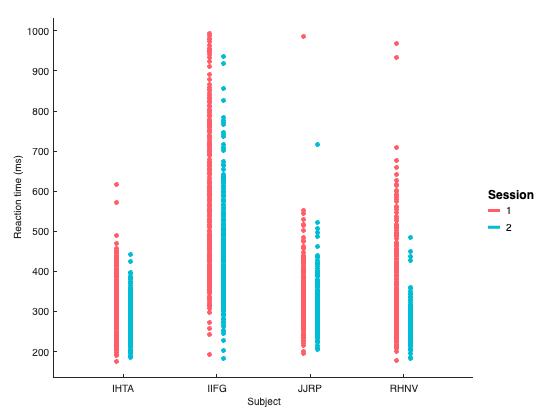

figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_point('dodge',0.3);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

Here we see that even with using the 'dodge' argument, the basic `geom_point()` is limited becaus of the overlap between points. We have two other `geom_` methods that can make this better. 

## Improving the visualization of raw datapoints

### Randomly jitter points with geom_jitter()

A first option is to use geom_jitter() instead of geom_point() so that the datapoins are jittered along the x-axis. 

To note:

- The `'width' `parameter sets the width along the x axis used for jittering, here setting it below half the value used for `'dodge'` allows for a small spacing between points for session 1 and 2. Setting a larger value could make the points overlap.

- We will also make the individual points transparent with the `'alpha' `parameter

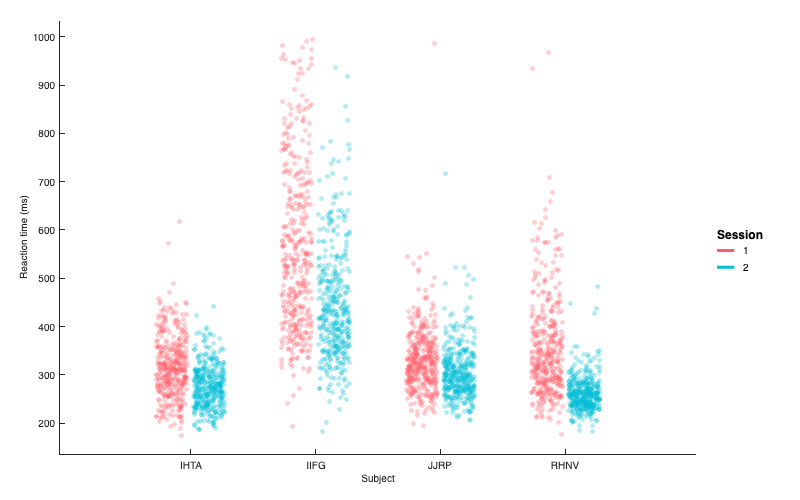

figure('Position',[100 100 800 500])
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_jitter('dodge',0.6,'width',0.25,'alpha',0.3);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

Here we better visualize the underlying distribution, however it's still difficult to get an idea with the mass of points in the middle of the distribution.

### Create a beeswarm plot with geom_swarm()

Another option to display raw datapoints is to to use a swarm plot, which stacks datapoints horizontally

**To note:** Here we set the 'point_size' parameter for geom_swarm() given the large amount of points in our dataset. geom_swarm is designed so that points within a group never overlap, so big points would make each swarm large.

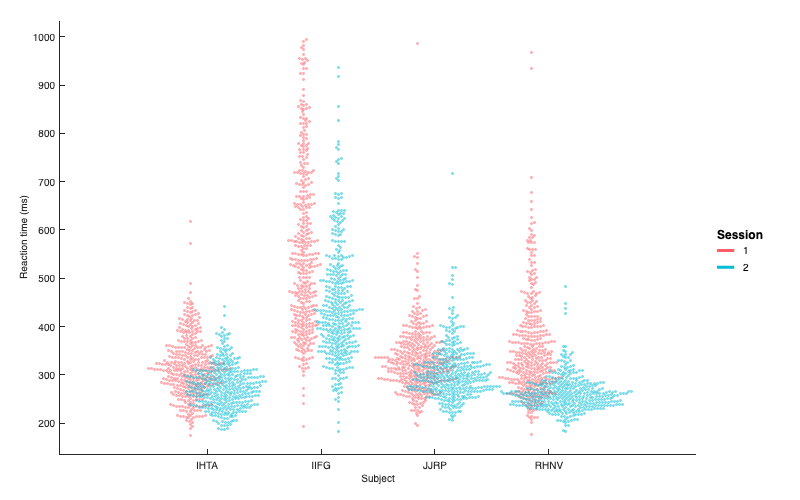

figure('Position',[100 100 800 500])
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.geom_swarm('dodge',0.6,'point_size',1.5,'alpha',0.5);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

## Adding statistics layers

Now that our we displayed our raw dataset, we can add more statistics oriented visualizations to our graphs.

### Visualize distributions

#### Boxplots

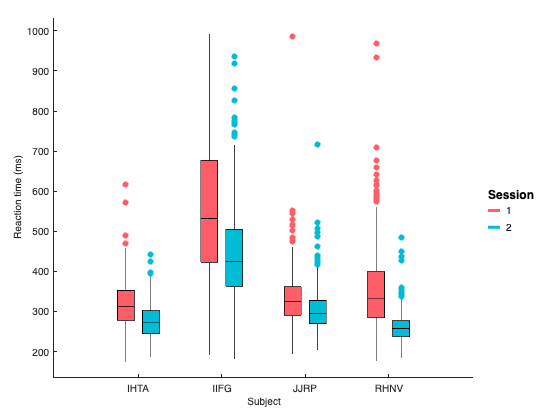

figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.stat_boxplot('dodge',0.6, 'width',0.4);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

#### Violin plots

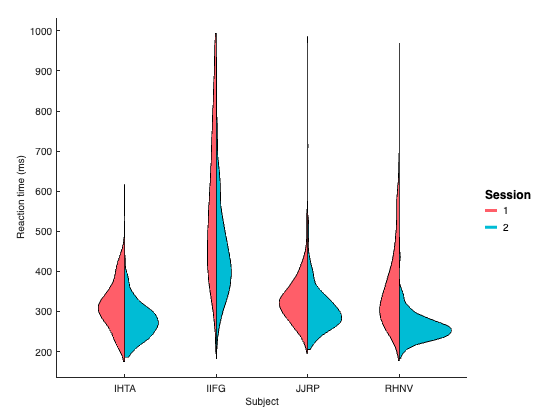

figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.stat_violin('dodge',0.6, 'width',0.3,'half',true);
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

### Summarize data

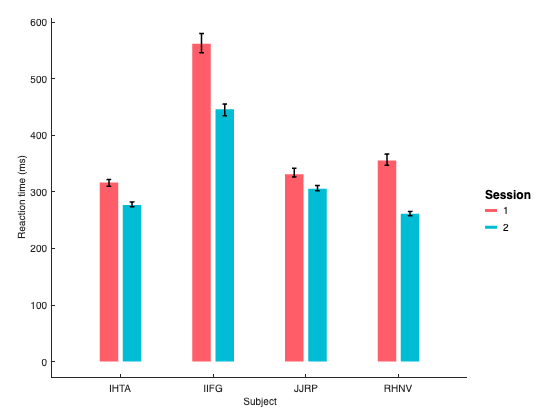

figure
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.session);
g.stat_summary('dodge',0.5, 'width',0.4,'geom',{'bar','black_errorbar'},'setylim',true,'type','bootci');
g.set_names('x','Subject','y','Reaction time (ms)','color','Session');
g.draw();

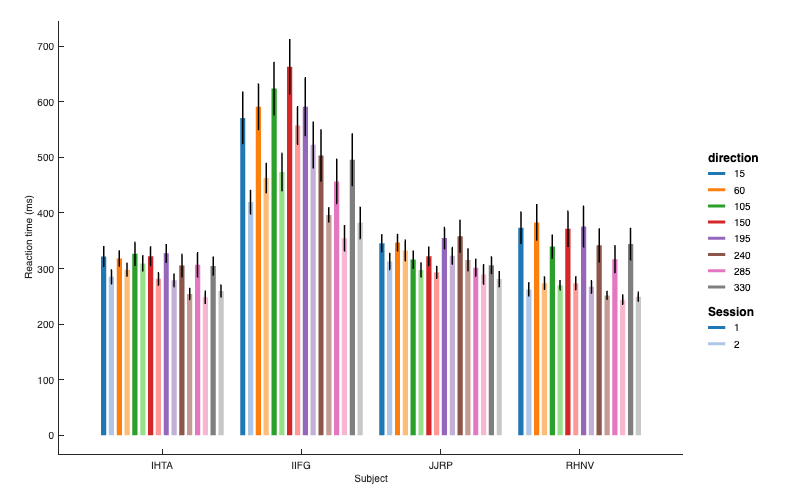

figure('Position',[100 100 800 500])
g=gramm('x',T.subject,'y',T.m_reaction_time,'color',T.reference_direction,'lightness',T.session);
g.stat_summary('dodge',0.9, 'width',0.6,'geom',{'bar','black_errorbar'},'setylim',true);
g.set_names('x','Subject','y','Reaction time (ms)','lightness','Session','color','direction');
g.set_color_options('map','d3_20');
g.draw();